clear
% Load observations and inputs
data = load('Assignment1_ObservationsAndInputs.txt');
y_obs = data(1, :);  % First row: actual observed outputs
u = data(2, :);      % Second row: input values
k = 1

k = 1


% Define ARX model parameters (from previous Q1.1 solution)
s.A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
s.B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];

N = length(y_obs);  % Total number of observations
m = 2;  % Prediction horizon (can be adjusted)

[G,S] = diophantine(s.A,1,m)

G =     1.0000    3.8810


S =     9.4148  -18.2654   13.2863   -3.4357


R = conv(s.B,G)

R =     0.4453    0.0172   -4.1424    8.0535   -5.9653    1.5917




% Initialize predicted values
offset = numel(s.B)+max([numel(S),numel(s.B),numel(R)])+k

offset = 12

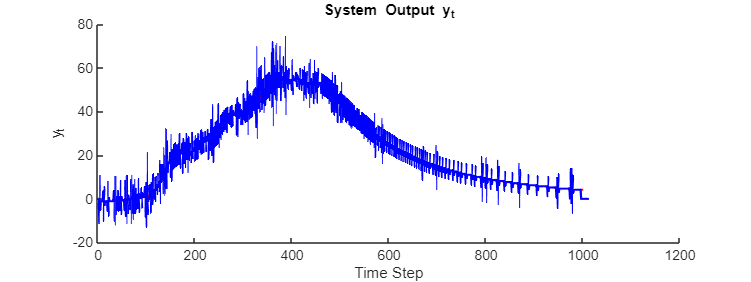

y_pred = [zeros(1, offset),zeros(1, N)];  % Store predictions
y_sampl =  [zeros(offset,1);y_obs'];
u_sampl = [zeros(offset,1);u'];

% u = zeros(1,N)
% Simulate predictions iteratively
for t = numel(s.B)+max([numel(S),numel(s.B),numel(R)])+k:N-numel(R) - k + offset
    % Predict y_{t+m} using the ARX equation
    % y_pred(t+m) = R* u_data(t+m-k+(0:numel(R)-1)) + S * s.y(t-(0:numel(S)-1));
    Rterm(t) = R* u_sampl(t+m-numel(s.B)-k-(0:numel(R)-1));
    Sterm(t) = S * y_sampl(t-(0:numel(S)-1));
    y_pred(t+m-offset) =  Rterm(t) + Sterm(t);
end




%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
hold on
plot(y_obs, 'r', 'LineWidth', 1.5);
plot(movmean(y_pred,1), 'b', 'LineWidth', 1.5);
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');

% grid on;
% subplot(2,1,2);
% plot(s.u, 'r', 'LineWidth', 1.5);
% title('Control Input u_t');
% xlabel('Time Step');
% ylabel('u_t');
% grid on;